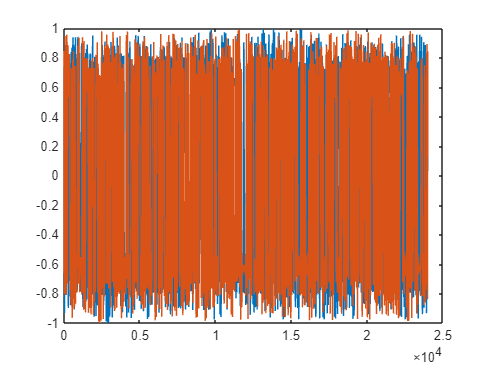

clc;
clc;
clear;
fs=100e6;
fc=0e6;
Rb=5e6;
sps=fs/Rb;
data=readmatrix("qpskbaseband.csv");
% plot(data(5:end));
% data=load("1123.mat");
% scatterplot(data);
i1=data(:,1);
q1=data(:,2);
t=0:1/fs:(length(q1)-1)/fs;
t=t.';
sn_i =i1.*cos(2*pi*fc.*t(1:length(i1)));   % I路的相干解调   只取实部
sn_q =  -i1.*sin(2*pi*fc.*t(1:length(i1)));  % Q路的相干解调
% i1=real(data);
% q1=imag(data.Y);
plot(i1);hold on;
plot(q1);hold off;

aa=sn_i+j*sn_q;
% scatterplot(aa);
% data1=data(140372:177546);
% plot(data1);

spectrumScope = spectrumAnalyzer("SampleRate",fs, ...
                "ViewType","spectrum", ...
                "SpectrumType","power", ...
                "PlotAsTwoSidedSpectrum",true, ...
                "Method","welch", ...
                "AveragingMethod","exponential", ...
                "SpectrumUnits", "dBm", ...
                "AxesScaling", "Manual", ...
                "YLimits", [-80 +0], ...
                "ForgettingFactor", 0.95, ...
                "FrequencyOffset", 0);
rolloff=0.35;
rctFilt = comm.RaisedCosineReceiveFilter(...
    'Shape', 'Square root', ...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', 20 ,...
    'InputSamplesPerSymbol',25,...
  DecimationFactor =1);
cc=rctFilt(aa);
% spectrumScope(cc);
scatterplot(cc(20*sps/2:sps:end));
% release(spectrumScope);

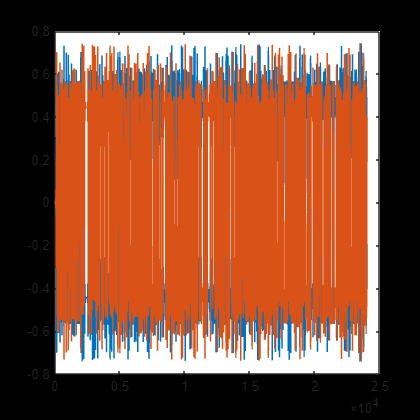

%下变频
%%% 相干解调
t=0:1/fs:(length(q1)-1)/fs;
t=t.';
txRF=q1(1:end);
% i1=i1(0:end);
sn_i =i1.*cos(2*pi*fc.*t(1:length(i1))+pi/4);   % I路的相干解调   只取实部
sn_q =  -i1.*sin(2*pi*fc.*t(1:length(i1))+pi/4);  % Q路的相干解调
plot(real(sn_i));hold on;
plot(real(sn_q));hold off;
% FIR低通滤波
lowpass_Fs=fs;          % 低通滤波器的采样频率
lowpass_Fpass=Rb;       % 低通滤波器的通带截止频率
lowpass_Fstop=Rb+Rb/10;   % 低通滤波器的阻带起始频率
% 下一行的lowpass是用fdatool设计的滤波器保存为matlab code自己修改了一下
dee=designfilt("lowpassfir",FilterOrder=200, ...
    CutoffFrequency=Rb*0.5,SampleRate=fs);
idata=filter(dee,sn_i);
qdata=filter(dee,sn_q);

plot(real(idata));hold on;
plot(real(qdata));hold off;

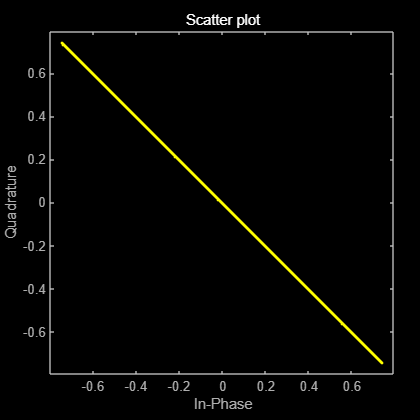

a=idata+1i*qdata;
% a=a(sps*3+20:sps:end);
%  scatterplot(a);
% [lowpass_b,lowpass_a] = tf(lowpass(lowpass_Fs,lowpass_Fpass,lowpass_Fstop));% 得到滤波器系数
% sn_i_lp = conv(sn_i,lowpass_b);   % I路低通滤波
% sn_i_lp = sn_i_lp(round(length(lowpass_b)/2):end-round(length(lowpass_b)/2)+1);
% sn_q_lp = conv(sn_q,lowpass_b);   % Q路低通滤波
% sn_q_lp = sn_q_lp(round(length(lowpass_b)/2):end-round(length(lowpass_b)/2)+1);
%匹配滤波器
cc=aa.*exp(-j*2*pi*fc*t);
% spectrumScope(cc);
rolloff=0.35;
rctFilt = comm.RaisedCosineReceiveFilter(...
    'Shape', 'Square root', ...
    'RolloffFactor', rolloff, ...
    'FilterSpanInSymbols', 10 ,...
  DecimationFactor =1);
% a=sn_i_lp+1i*sn_q_lp;
b=rctFilt(a).*exp(-j*pi*3/4);
b=a;
% b=rctFilt(cc)
scatterplot(b);

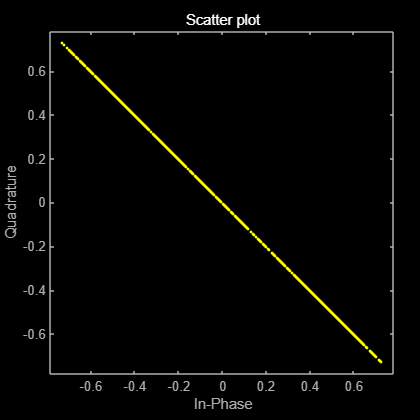

v=1;
scatterplot(b(sps*4+0:sps:end));